% Derive the forward kinematics equations
close all
clear all
clc
syms l_pp l_dp l_ip  theta_mcp(t) theta_dip(t) theta_pip(t) theta_abd(t) t
x_mcp = l_pp* cos(theta_mcp);
y_mcp = l_pp* sin(theta_mcp);
x_dip = x_mcp + l_ip*cos(theta_mcp-theta_pip);
y_dip = y_mcp + l_ip*sin(theta_mcp-theta_pip);
xe = x_dip + l_dp*cos(theta_mcp-theta_pip-theta_dip)

$$xe(t) = l_{\mathrm{pp}}\,\cos\left(\theta_{\mathrm{mcp}}\left(t\right)\right)+l_{\mathrm{dp}}\,\cos\left(\theta_{\mathrm{dip}}\left(t\right)-\theta_{\mathrm{mcp}}\left(t\right)+\theta_{\mathrm{pip}}\left(t\right)\right)+l_{\mathrm{ip}}\,\cos\left(\theta_{\mathrm{mcp}}\left(t\right)-\theta_{\mathrm{pip}}\left(t\right)\right)$$

ye = y_dip + l_dp*sin(theta_mcp-theta_pip-theta_dip)

$$ye(t) = l_{\mathrm{pp}}\,\sin\left(\theta_{\mathrm{mcp}}\left(t\right)\right)-l_{\mathrm{dp}}\,\sin\left(\theta_{\mathrm{dip}}\left(t\right)-\theta_{\mathrm{mcp}}\left(t\right)+\theta_{\mathrm{pip}}\left(t\right)\right)+l_{\mathrm{ip}}\,\sin\left(\theta_{\mathrm{mcp}}\left(t\right)-\theta_{\mathrm{pip}}\left(t\right)\right)$$

dxe = diff(xe,t)

$$dxe(t) = -l_{\mathrm{ip}}\,\sin\left(\theta_{\mathrm{mcp}}\left(t\right)-\theta_{\mathrm{pip}}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{\mathrm{mcp}}\left(t\right)-\frac{\partial }{\partial t}\theta_{\mathrm{pip}}\left(t\right)\right)-l_{\mathrm{dp}}\,\sin\left(\theta_{\mathrm{dip}}\left(t\right)-\theta_{\mathrm{mcp}}\left(t\right)+\theta_{\mathrm{pip}}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{\mathrm{dip}}\left(t\right)-\frac{\partial }{\partial t}\theta_{\mathrm{mcp}}\left(t\right)+\frac{\partial }{\partial t}\theta_{\mathrm{pip}}\left(t\right)\right)-l_{\mathrm{pp}}\,\sin\left(\theta_{\mathrm{mcp}}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{mcp}}\left(t\right)$$

dye = diff(ye,t)

$$dye(t) = l_{\mathrm{pp}}\,\cos\left(\theta_{\mathrm{mcp}}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{mcp}}\left(t\right)-l_{\mathrm{dp}}\,\cos\left(\theta_{\mathrm{dip}}\left(t\right)-\theta_{\mathrm{mcp}}\left(t\right)+\theta_{\mathrm{pip}}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{\mathrm{dip}}\left(t\right)-\frac{\partial }{\partial t}\theta_{\mathrm{mcp}}\left(t\right)+\frac{\partial }{\partial t}\theta_{\mathrm{pip}}\left(t\right)\right)+l_{\mathrm{ip}}\,\cos\left(\theta_{\mathrm{mcp}}\left(t\right)-\theta_{\mathrm{pip}}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}\theta_{\mathrm{mcp}}\left(t\right)-\frac{\partial }{\partial t}\theta_{\mathrm{pip}}\left(t\right)\right)$$


% Clearly we have 2 equations and 3 unknowns
% There exists infinitely many solutions

theta_e=theta_mcp-theta_pip-theta_dip

$$theta\_e(t) = \theta_{\mathrm{mcp}}\left(t\right)-\theta_{\mathrm{dip}}\left(t\right)-\theta_{\mathrm{pip}}\left(t\right)$$


% We will have 3 equations with 3 unknowns, 
% there will be two solutions DIP up and DIP down.


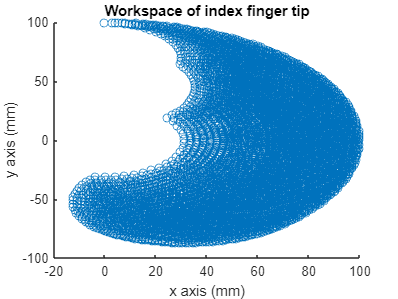

%define coordinates to plot the workspace of the fingertip
q1i=-45;
q1f=90;
q2i=0;
q2f=100;
q3i=0;
q3f=80;
l_pp =45;
l_dp = 30;
l_ip = 25;
theta_mcp= deg2rad(linspace(q1i,q1f,20));
theta_pip = deg2rad(linspace(q2i,q2f,20));
theta_dip = deg2rad(linspace(q3i,q3f,20));
a=1;
for i=1:length(theta_mcp)
    for j=1:length(theta_dip)
        for k=1:length(theta_pip)
            x0=0;
            y0=0;
            x1 = l_pp* cos(theta_mcp(i));
            y1 = l_pp* sin(theta_mcp(i));
            x2 = x1 + l_ip*cos(theta_mcp(i)-theta_dip(j));
            y2 = y1 + l_ip*sin(theta_mcp(i)-theta_dip(j));
            x_e(a) = x2 + l_dp*cos(theta_mcp(i)-theta_dip(j)-theta_pip(k));
            y_e(a) = y2 + l_dp*sin(theta_mcp(i)-theta_dip(j)-theta_pip(k));
            a=a+1;
        end
    end
end

scatter(x_e,y_e)
xlabel('x axis (mm)')
ylabel('y axis (mm)')
title('Workspace of index finger tip')